## Prova de HOGS

clear
im = imread("brillant.png")

im = 118×114×3 uint8 array
im(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   254   254   253   254   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255
   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   25


[normalized,BW] = preProcesing(im)

normalized = 118×114×3 uint8 array
normalized(:,:,1) =

   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121
   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121   121 

BW = 118×114 logical array
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1 

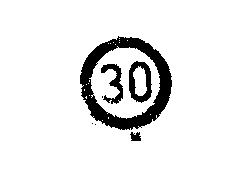

imshow(BW)


[a,b] = extractHOGFeatures(BW)

a = 1×6084 single row vector
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


b = Visualization

   Type plot(b) to visualize.

   Read-only properties:
                CellSize: [8 8]
               BlockSize: [2 2]
            BlockOverlap: [1 1]
                 NumBins: 9
    UseSignedOrientation: 0
              BinCenters: [18×1 double]


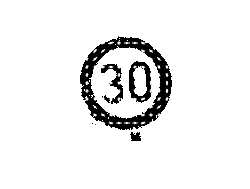


figure;
imshow(BW); 
hold on;
plot(b);